# Filtro de Kalman em um robô 1D

#### Glauber R. Leite

### Modelagem do problema

Consideramos um robô 1D descrito pela seguinte equação diferença:


$$\frac{v_r \left(k+1\right)-v_r \left(k\right)}{T}=\frac{u\left(k\right)}{m}$$


Em que $v_r$ é a velocidade, $u\left(k\right)$é a entrada de força, $m$ é a massa do robô e $T$ é o tempo de amostragem.

considerando $x_r$ a posição do robô, temos o seguinte vetor de estados:


$$x={\left\lbrack \begin{array}{cc}
x_r  & v_r 
\end{array}\right\rbrack }^T$$


A partir da equação de velocidade, calculamos $x_r \left(k+1\right)$:


$$v_r \left(k\right)=\frac{x_r \left(k+1\right)-x_r \left(k\right)}{T}\Rightarrow x_r \left(k+1\right)=1\cdot x_r \left(k\right)+T\cdot v_r \left(k\right)+0\cdot u\left(k\right)$$


A partir da equação diferença, calculamos $v_r \left(k+1\right)$:


$$v_r \left(k+1\right)=0\cdot x\left(k\right)+1\cdot v_r \left(k\right)+\left(\frac{T}{m}\right)\cdot u\left(k\right)$$


Assim, o processo é descrito pela seguinte equação:


$$x\left(k+1\right)=\left\lbrack \begin{array}{cc}
1 & T\\
0 & 1
\end{array}\right\rbrack x\left(k\right)+\left\lbrack \begin{array}{c}
0\\
\frac{T}{m}
\end{array}\right\rbrack u\left(k\right)+\upsilon \left(k\right)$$


De forma que $\upsilon \left(k\right)$ é o ruído de processo.

Usando um sensor de velocidade, com ruído caracterizado por $\omega \left(k\right)$, temos a seguinte equação de saída:


$$y\left(k+1\right)=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack \;x\left(k\right)+\omega \left(k\right)$$


### Dados do problema

m = 1;
T = 0.5;
V = [0.2, 0.05; 0.05, 0.1]; % Process noise covariance matrix
W = 0.5; % Output noise variance

Matrizes da modelagem fenomenológica:

F = [1, T; 0, 1];
G = [0; T/m];
H = [0, 1];

O problema original trabalha com apenas uma iteração.. Como a atividade requer mais iterações. Vamos definir um número de iterações:

n_iter = 20;

Usaremos as condições iniciais originalmente descritas, mas para que tenhamos mais iterações será necessário especificar mais valores de entrada e saída que o sistema receberia durante essas iterações. Esses valores foram escolhidos arbitrariamente construindo um cenário aonde o robô vai parando.

% No more voltage
u = zeros(n_iter, 1);

Estimativa inicial e matriz de incerteza (oferecida no problema):

x = zeros(2, n_iter);
x(:, 1) = [2; 4];
P = zeros(2, 2, n_iter);
P(:, :, 1) = [1, 0; 0, 2];

Sabendo que o estado real na primeira iteração é $x\left(k+1\right)={\left\lbrack \begin{array}{cc}
1\ldotp 8 & 2
\end{array}\right\rbrack }^T$. Definimos o vetor de velocidades supostamente retornadas pelo sensor no decorrer das iterações, quando a velocidade do carro vai diminuindo, além de adicionar W*hite Gaussian Noise *com variância W = 0.5

% Based on the first real state, we compute the first ideal sensor reading
x_real = [1.8; 2];
y = zeros(n_iter, 1);
y(1) = H * x_real;
y(2) = y(1); % Just for later didatic purposes

% y must be zero at last iteration
dy = y(2)/(n_iter - 2);

for k = 3:n_iter
    y(k) = y(k-1) - dy;
end

% Adding White Gaussian Noise with y as mean
noise = rand(n_iter, 1)*sqrt(W);
y = y + noise;

### Implementação do filtro de Kalman

Aplicando as equações demonstradas em sala, temos os passos de predição e correção. Na primeira iteração, temos:

#### Predição

x(:, 2) = F*x(:, 1) + G*u(1);
P(:, :, 2) = F*P(:, :, 1)*F' + V;

Para visualizar a predição usamos o seguinte trecho de código:

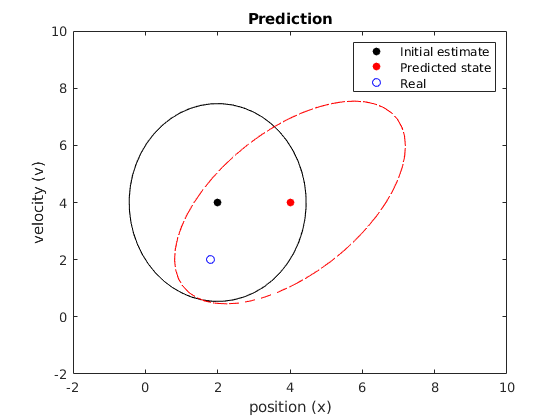

% Choosing confidence level to plot
p = 0.95;
% Computing scale factor
s = - 2 * log(1 - p);

% Computing eigenvalues of eigenvectors uncertainity matrix P
[V1, D1] = eig(P(:,:,1) * s);
[V2, D2] = eig(P(:,:,2) * s);

% Ellipse equation
vel = linspace(-2,10);
a = (V1 * sqrt(D1)) * [cos(vel(:))'; sin(vel(:))'];
b = (V2 * sqrt(D2)) * [cos(vel(:))'; sin(vel(:))'];

% Ploting ellipses with x as mean
plot(a(1, :) + x(1,1), a(2, :) + x(2,1), 'k-');
hold on;
plot(b(1, :) + x(1,2), b(2, :) + x(2,2), 'r--');

% Adding states
s1 = scatter(x(1,1), x(2,1), 'k', 'filled');
s2 = scatter(x(1,2), x(2,2), 'r', 'filled');
s3 = scatter(x_real(1), x_real(2), 'b');

legend([s1, s2, s3], {'Initial estimate', 'Predicted state', 'Real'});
title('Prediction');
xlabel('position (x)');
ylabel('velocity (v)');
axis([-2 10 -2 10]);
hold off;

#### Correção

R = P(:,:,2)*H'/(H*P(:,:,2)*H' + W);
nu = y(2) - H*x(:, 1);

% Saving predicted values (for plot)
x_predicted = x(:, 2);
P_predicted = P(:,:,2);

x(:, 2) = x(:, 2) + R*nu;
P(:,:,2) = P(:,:,2) - R*H*P(:,:,2);

Podemos plotar a iteração da seguinte maneira:

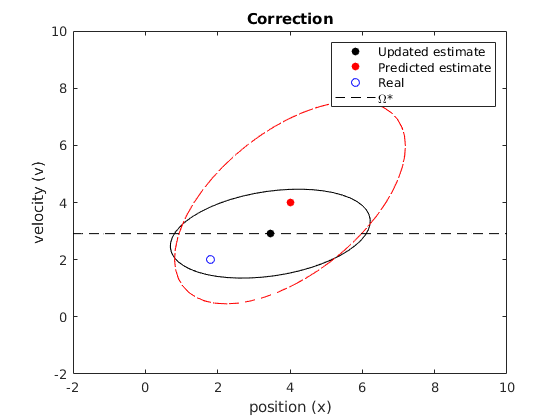

% Choosing confidence level to plot
p = 0.95;
% Computing scale factor
s = - 2 * log(1 - p);

% Computing eigenvalues of eigenvectors uncertainity matrix P
[V1, D1] = eig(P(:,:,2) * s);
[V2, D2] = eig(P_predicted * s);

% Ellipse equation
vel = linspace(-2,10);
a = (V1 * sqrt(D1)) * [cos(vel(:))'; sin(vel(:))'];
b = (V2 * sqrt(D2)) * [cos(vel(:))'; sin(vel(:))'];

% Ploting ellipses with x as mean
plot(a(1, :) + x(1,2), a(2, :) + x(2,2), 'k-');
hold on;
plot(b(1, :) + x_predicted(1), b(2, :) + x_predicted(2), 'r--');

% Adding states
s1 = scatter(x(1,2), x(2,2), 'k', 'filled');
s2 = scatter(x_predicted(1), x_predicted(2), 'r', 'filled');
s3 = scatter(x_real(1), x_real(2), 'b');

omega = ones(length(vel), 1) * x(2,2);
o1 = plot(vel, omega, 'k--');


legend([s1, s2, s3, o1], {'Updated estimate', 'Predicted estimate', 'Real', '\Omega*'});
title('Correction');
xlabel('position (x)');
ylabel('velocity (v)');
axis([-2 10 -2 10]);
hold off;

Agora aplicamos as iterações seguintes

for k = 3:n_iter
    % Prediction
    x(:, k) = F*x(:, k-1) + G*u(k-1);
    P(:, :, k) = F*P(:, :, k-1)*F' + V;
    
    % Correction
    R = P(:,:,k)*H'/(H*P(:,:,k)*H' + W);
    nu = y(k) - H*x(:, k-1);

    x(:, k) = x(:, k) + R*nu;
    P(:,:,k) = P(:,:,k) - R*H*P(:,:,k);
end

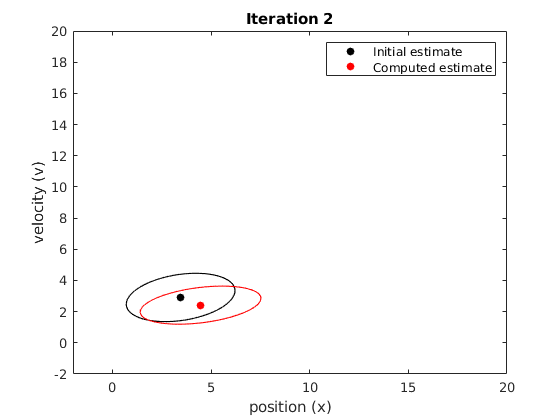

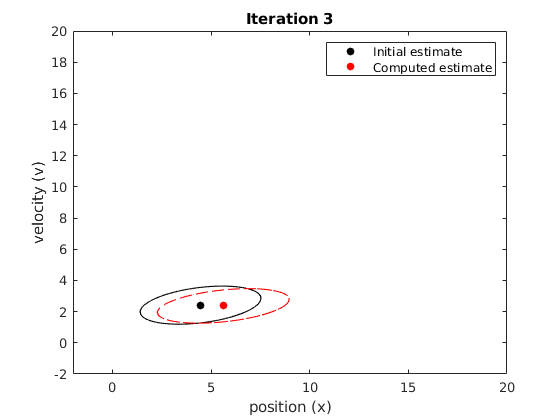

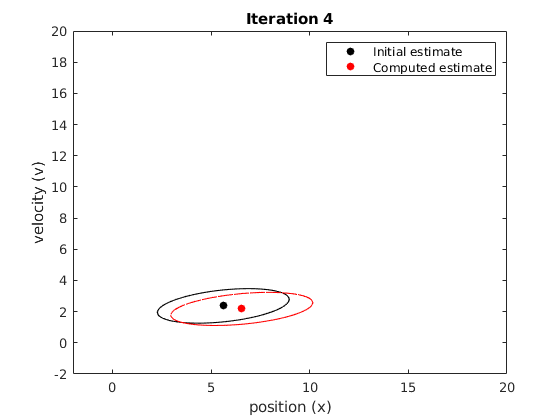

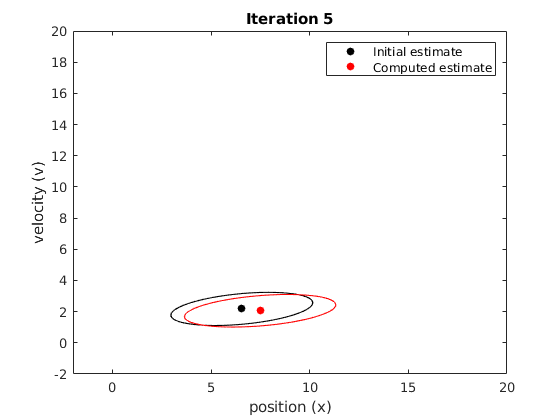

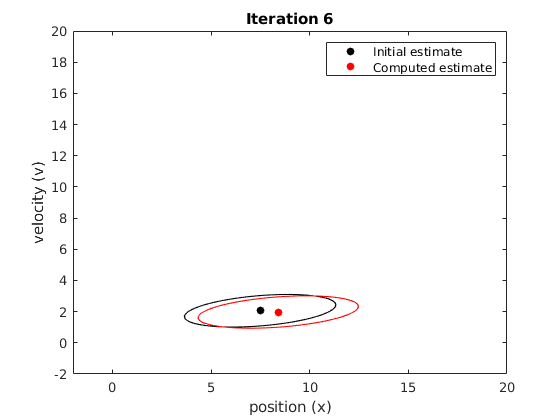

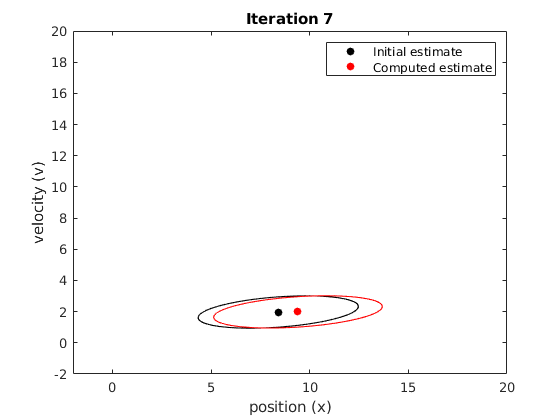

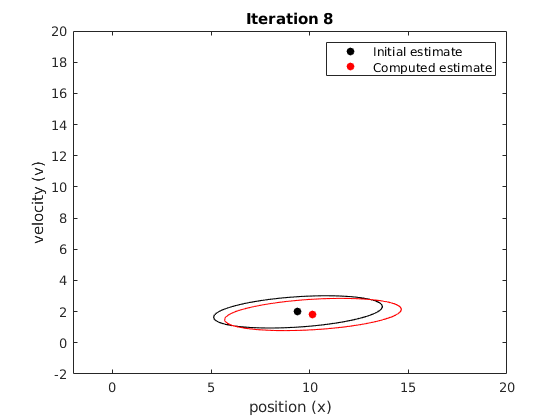

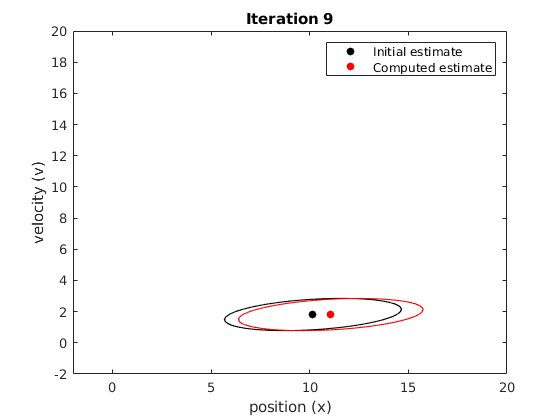

% Choosing confidence level to plot
p = 0.95;
% Computing scale factor
s = - 2 * log(1 - p);

for k = 3:n_iter
    % Computing eigenvalues of eigenvectors uncertainity matrix P
    [V1, D1] = eig(P(:,:,k-1) * s);
    [V2, D2] = eig(P(:,:,k) * s);
    
    % Ellipse equation
    vel = linspace(-2,20);
    a = (V1 * sqrt(D1)) * [cos(vel(:))'; sin(vel(:))'];
    b = (V2 * sqrt(D2)) * [cos(vel(:))'; sin(vel(:))'];
    
    % Ploting ellipses with x as mean
    figure
    plot(a(1, :) + x(1,k-1), a(2, :) + x(2,k-1), 'k-');
    hold on;
    plot(b(1, :) + x(1,k), b(2, :) + x(2,k), 'r--');
    
    % Adding states
    s1 = scatter(x(1,k-1), x(2,k-1), 'k', 'filled');
    s2 = scatter(x(1,k), x(2,k), 'r', 'filled');
    
    legend([s1, s2], {'Initial estimate', 'Computed estimate'});
    title(['Iteration ', num2str(k-1)]);
    xlabel('position (x)');
    ylabel('velocity (v)');
    axis([-2 20 -2 20]);
    hold off;
end